# Cleaning Workspace

clear;
close all;
clc;

# Initialization Parameters

## Ploting Parameters

linewidth  = 2;
fontname   = 'Times New Roman';
fontsize   = 20;
markersize = 10;

colors = [0.0000 0.0000 0.0000;
          0.0000 0.4470 0.7410;
          0.8500 0.3250 0.0980;
          0.9290 0.6940 0.1250;
          0.4940 0.1840 0.5560;
          0.4660 0.6740 0.1880;
          0.3010 0.7450 0.9330;
          0.6350 0.0780 0.1840];

# Communication System

## Data Transmission Parameters

Parameters related to the data transmission, e.g., number of bits, constellation size, number of subcarriers, and number of transmitted blocks.

B     = [3 4];                   % Number of bits in a symbol
Q     = 2.^B;                    % Constellation size
M     = [16 32 64 128 256];      % Number of subcarriers
K     = 15;                      %
N     = M+K;                     %
N_BLK = 10000;                   % The number of transmitted data blocks

N_BIN = 30;

x = cell(length(B),length(M),4);
papr = zeros(N_BLK,length(B),length(M),4);

cdf_papr = zeros(N_BIN,length(B),length(M),4);
edg_papr = zeros(N_BIN+1,length(B),length(M),4);

paprMeter = powermeter(ComputeCCDF=true,Measurement='Peak-to-average power ratio');

for b_ind = 1:length(B)
    for m_ind = 1:length(M)
        A_cp = [zeros(K,M(m_ind)-K) eye(K); eye(M(m_ind))];
        R_cp = [zeros(M(m_ind),K) eye(M(m_ind))];

        A_zp = [eye(M(m_ind)); zeros(K,M(m_ind))];
        R_zp = [eye(M(m_ind)) [eye(K); zeros(M(m_ind)-K,K)]];

        m_bit = randi([0 1],B(b_ind)*M(m_ind),N_BLK);
        m_mod = qammod(m_bit,Q(b_ind),'InputType','bit'); % Q-QAM modulation
    
        x{b_ind,m_ind,1} = A_cp*m_mod;
        x{b_ind,m_ind,2} = A_zp*m_mod;
        x{b_ind,m_ind,3} = sqrt(M(m_ind))*A_cp*ifft(m_mod);
        x{b_ind,m_ind,4} = sqrt(M(m_ind))*A_zp*ifft(m_mod);

        papr(:,b_ind,m_ind,1) = paprMeter(x{b_ind,m_ind,1});
        release(paprMeter);
        papr(:,b_ind,m_ind,2) = paprMeter(x{b_ind,m_ind,2});
        release(paprMeter);
        papr(:,b_ind,m_ind,3) = paprMeter(x{b_ind,m_ind,3});
        release(paprMeter);
        papr(:,b_ind,m_ind,4) = paprMeter(x{b_ind,m_ind,4});
        release(paprMeter);

        [cdf_papr(:,b_ind,m_ind,1),edg_papr(:,b_ind,m_ind,1)] = histcounts(papr(:,b_ind,m_ind,1),N_BIN,'normalization','cdf');
        [cdf_papr(:,b_ind,m_ind,2),edg_papr(:,b_ind,m_ind,2)] = histcounts(papr(:,b_ind,m_ind,2),N_BIN,'normalization','cdf');
        [cdf_papr(:,b_ind,m_ind,3),edg_papr(:,b_ind,m_ind,3)] = histcounts(papr(:,b_ind,m_ind,3),N_BIN,'normalization','cdf');
        [cdf_papr(:,b_ind,m_ind,4),edg_papr(:,b_ind,m_ind,4)] = histcounts(papr(:,b_ind,m_ind,4),N_BIN,'normalization','cdf');
    end
end

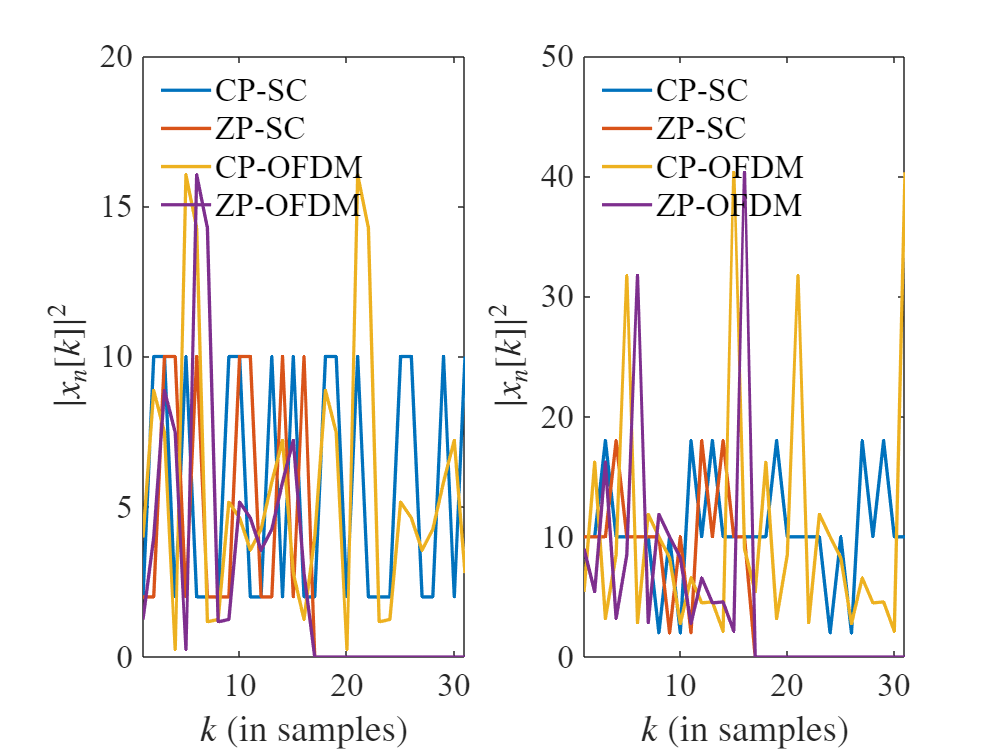

figure;

set(gcf,'position',[0 0 800 600]);

for b_ind = 1:length(B)
    subplot(1,2,b_ind);

    plot(1:N(1),abs(x{b_ind,1,1}(:,1).^2),'-','color',colors(2,:),'linewidth',linewidth);
    hold on;
    plot(1:N(1),abs(x{b_ind,1,2}(:,1).^2),'-','color',colors(3,:),'linewidth',linewidth);
    plot(1:N(1),abs(x{b_ind,1,3}(:,1).^2),'-','color',colors(4,:),'linewidth',linewidth);
    plot(1:N(1),abs(x{b_ind,1,4}(:,1).^2),'-','color',colors(5,:),'linewidth',linewidth);
    
    xlabel('$k$ (in samples)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
    ylabel('$|x_{n}[k]|^{2}$','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

    legend({'CP-SC','ZP-SC','CP-OFDM','ZP-OFDM'},'fontname',fontname,'fontsize',fontsize,'location','northwest')
    legend box off

    xlim([1 N(1)]);

    set(gca,'fontname',fontname,'fontsize',fontsize);
end

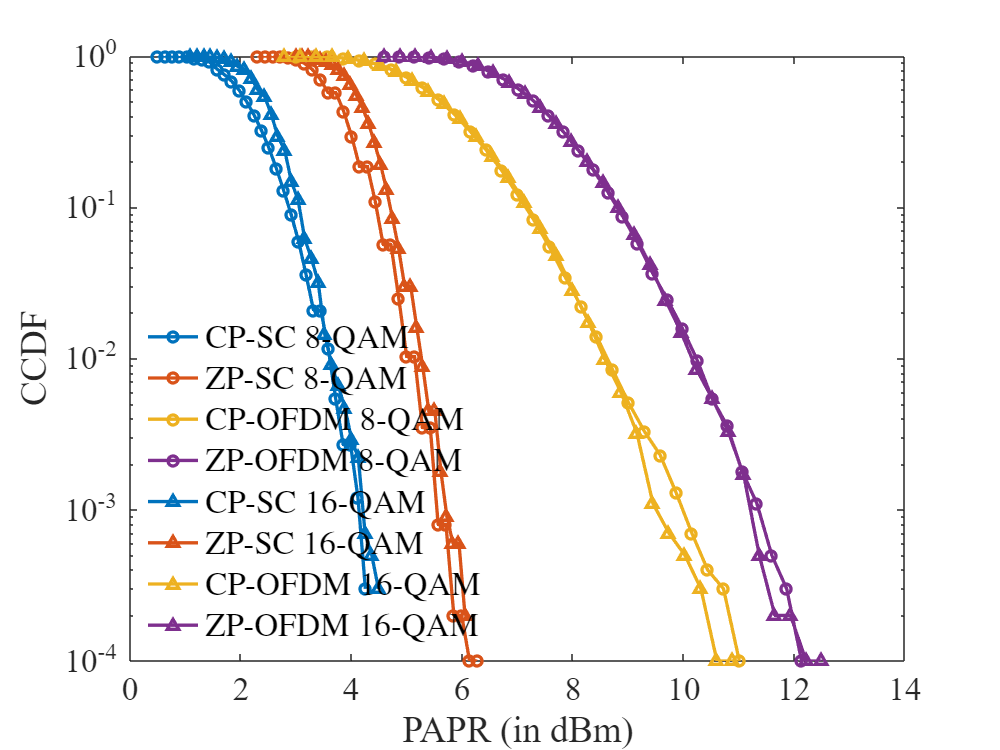

figure;

set(gcf,'position',[0 0 800 600]);

semilogy(edg_papr(1:end-2,1,2,1),1-cdf_papr(1:end-1,1,2,1),'o-','color',colors(2,:),'linewidth',linewidth);
hold on;
semilogy(edg_papr(1:end-2,1,2,2),1-cdf_papr(1:end-1,1,2,2),'o-','color',colors(3,:),'linewidth',linewidth);
semilogy(edg_papr(1:end-2,1,2,3),1-cdf_papr(1:end-1,1,2,3),'o-','color',colors(4,:),'linewidth',linewidth);
semilogy(edg_papr(1:end-2,1,2,4),1-cdf_papr(1:end-1,1,2,4),'o-','color',colors(5,:),'linewidth',linewidth);
semilogy(edg_papr(1:end-2,2,2,1),1-cdf_papr(1:end-1,2,2,1),'^-','color',colors(2,:),'linewidth',linewidth);
semilogy(edg_papr(1:end-2,2,2,2),1-cdf_papr(1:end-1,2,2,2),'^-','color',colors(3,:),'linewidth',linewidth);
semilogy(edg_papr(1:end-2,2,2,3),1-cdf_papr(1:end-1,2,2,3),'^-','color',colors(4,:),'linewidth',linewidth);
semilogy(edg_papr(1:end-2,2,2,4),1-cdf_papr(1:end-1,2,2,4),'^-','color',colors(5,:),'linewidth',linewidth);

xlabel('PAPR (in dBm)','fontname',fontname,'fontsize',fontsize);
ylabel('CCDF','fontname',fontname,'fontsize',fontsize);

legend({'CP-SC 8-QAM','ZP-SC 8-QAM','CP-OFDM 8-QAM','ZP-OFDM 8-QAM','CP-SC 16-QAM','ZP-SC 16-QAM','CP-OFDM 16-QAM','ZP-OFDM 16-QAM'}, ...
    'fontname',fontname,'fontsize',fontsize,'interpreter','latex','location','southwest')
legend box off

% xlim([-5 10]);

set(gca,'fontname',fontname,'fontsize',fontsize);

% figure;
% 
% set(gcf,'position',[0 0 800 600]);
% 
% semilogy(edg_papr(1:end-2,2,1,1),1-cdf_papr(1:end-1,2,1,1),'-' ,'color',colors(2,:),'linewidth',linewidth);
% hold on;
% semilogy(edg_papr(1:end-2,2,1,2),1-cdf_papr(1:end-1,2,1,2),'--','color',colors(2,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,1,3),1-cdf_papr(1:end-1,2,1,3),'.-','color',colors(2,:),'linewidth',linewidth);
% %hold on;
% semilogy(edg_papr(1:end-2,2,1,4),1-cdf_papr(1:end-1,2,1,4),':' ,'color',colors(2,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,2,1),1-cdf_papr(1:end-1,2,2,1),'-' ,'color',colors(3,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,2,2),1-cdf_papr(1:end-1,2,2,2),'--','color',colors(3,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,2,3),1-cdf_papr(1:end-1,2,2,3),'.-','color',colors(3,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,2,4),1-cdf_papr(1:end-1,2,2,4),':' ,'color',colors(3,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,3,1),1-cdf_papr(1:end-1,2,3,1),'-' ,'color',colors(4,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,3,2),1-cdf_papr(1:end-1,2,3,2),'--','color',colors(4,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,3,3),1-cdf_papr(1:end-1,2,3,3),'.-','color',colors(4,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,3,4),1-cdf_papr(1:end-1,2,3,4),':' ,'color',colors(4,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,4,1),1-cdf_papr(1:end-1,2,4,1),'-' ,'color',colors(5,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,4,2),1-cdf_papr(1:end-1,2,4,2),'--','color',colors(5,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,4,3),1-cdf_papr(1:end-1,2,4,3),'.-','color',colors(5,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,4,4),1-cdf_papr(1:end-1,2,4,4),':' ,'color',colors(5,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,5,1),1-cdf_papr(1:end-1,2,5,1),'-' ,'color',colors(6,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,5,2),1-cdf_papr(1:end-1,2,5,2),'--','color',colors(6,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,5,3),1-cdf_papr(1:end-1,2,5,3),'.-','color',colors(6,:),'linewidth',linewidth);
% semilogy(edg_papr(1:end-2,2,5,4),1-cdf_papr(1:end-1,2,5,4),':' ,'color',colors(6,:),'linewidth',linewidth);